map = load("multilayerMap.mat").map;

binaryMap = map(:,:,1);
speedMap = map(:,:,2);
trafficMap = map(:,:,3);
obstacleMap = map(:,:,4);

Binary Map Display

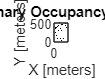

binaryOccMap = binaryOccupancyMap(binaryMap);
show(binaryOccMap)

Speed Limit Cost Map

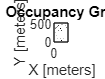

costMap_normalized = speedMap./max(max(speedMap));
speedOccMap = occupancyMap(costMap_normalized);

show(speedOccMap)

Traffic Intensity

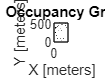

trafficMap_normalized = trafficMap./max(max(trafficMap));
trafficOccMap = occupancyMap(trafficMap_normalized);

show(trafficOccMap)

Obstacle Map

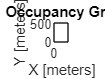

obstacleMap_normalized = obstacleMap./max(max(obstacleMap));
obstacleOccMap = occupancyMap(obstacleMap_normalized);

show(obstacleOccMap)

Full Cost Map

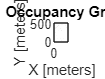

cost = speedMap .* trafficMap + obstacleMap;

costMap_normalized = cost./max(max(cost));
costOccMap = occupancyMap(costMap_normalized);

show(costOccMap)

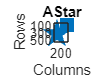

[startPoint, stopPoint] = startStopGenerator(binaryMap);
planner = plannerAStarGrid(costOccMap);
plan(planner,startPoint,stopPoint);
show(planner)

test_map = costMap_normalized*0.99;
test_map(test_map==0) = 1;
testOccMap = occupancyMap(test_map);

[startPoint, stopPoint] = startStopGenerator(binaryMap);
planner = plannerAStarGrid(testOccMap);
path = plan(planner,startPoint,stopPoint);

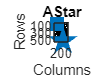

show(planner)

for i=1:1:100
    [startPoint, stopPoint] = startStopGenerator(binaryMap);
    a = length(task_1(map, startPoint, stopPoint))
    if a == 0
        disp("dupa")
    end
end

a = 301

a = 398

a = 396

a = 434

a = 279

a = 434

a = 292

a = 368

a = 375

a = 430

a = 447

a = 340

a = 486

a = 393

a = 356

a = 398

a = 424

a = 390

a = 424

a = 413

a = 413

a = 360

a = 452

a = 453

a = 275

a = 402

a = 475

a = 392

a = 502

a = 397

a = 462

a = 453

a = 314

a = 357

a = 442

a = 421

a = 441

a = 277

a = 277

a = 343

a = 428

a = 390

a = 427

a = 381

a = 274

a = 371

a = 528

a = 322

a = 443

a = 463

a = 448

a = 451

a = 525

a = 445

a = 515

a = 430

a = 458

a = 417

a = 380

a = 542

a = 363

a = 428

a = 397

a = 413

a = 375

a = 322

a = 383

a = 303

a = 458

a = 427

a = 444

a = 403

a = 417

a = 282

a = 527

a = 269

a = 420

a = 377

a = 410

a = 521

a = 433

a = 317

a = 388

a = 456

a = 267

a = 347

a = 372

a = 273

a = 283

a = 295

a = 458

a = 361

a = 414

a = 306

a = 420

a = 382

a = 357

a = 377

a = 304

a = 375